# Polyphase Channelizer

This testbench generates input stimulus for the Versal polyphase channelizer implementation, simulates the channelizer in Simulink, and compares the output of the Simulink model to the MATLAB golden reference.

## Preparation

clear;
close all;

## Initialize the Channelizer Model

Specify fixed-point quantization of the AI Engine channelizer implementation:

TT = numerictype(1,16,15);
FF = fimath('RoundingMethod','Nearest','OverflowAction','Saturate');

## Create Testbench Stimulus & Golden Reference for Full Channelizer

mdl = channelizer_init(TT, FF);
channelizer = channelizer_model(mdl, TT, FF );

## Run Channelizer Simulink Model

set_param('Channelizer', 'SimulationCommand', 'start');

Wait for the Simulink model to finish execution before proceeding to the next section.

status = get_param(bdroot, 'SimulationStatus');
while ~strcmp(status, 'stopped')
    pause(1);
    status = get_param(bdroot, 'SimulationStatus');
end

## Check Simulink Outputs against MATLAB Reference

Plot the output of the Simulink model against the MATLAB golden reference, and calculate the difference/error.

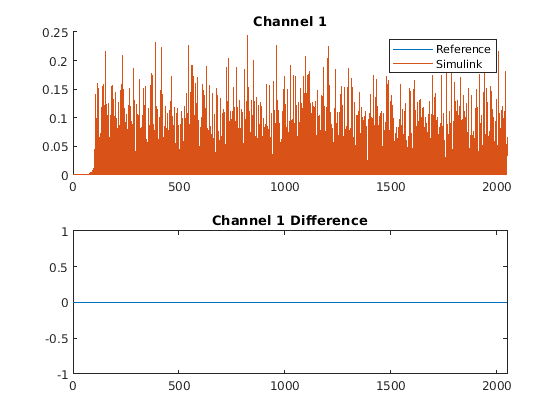

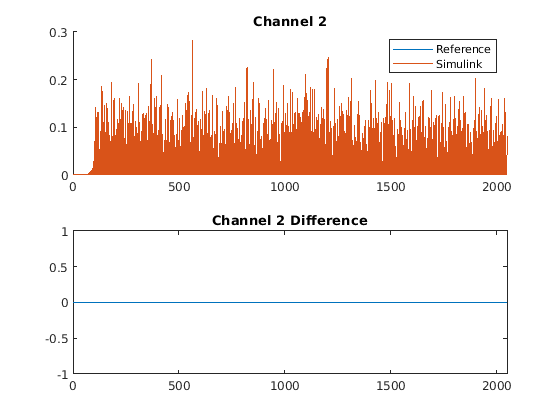

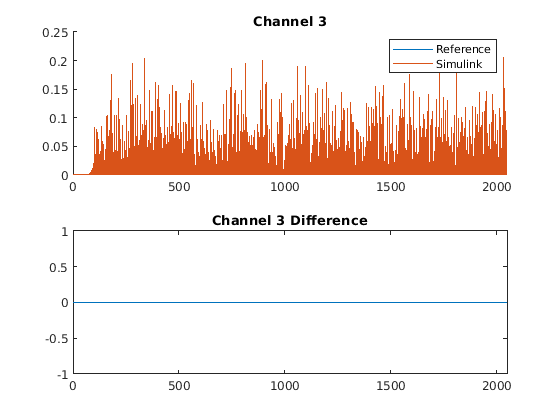

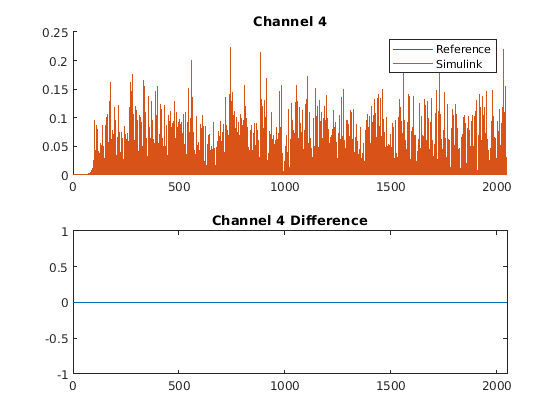

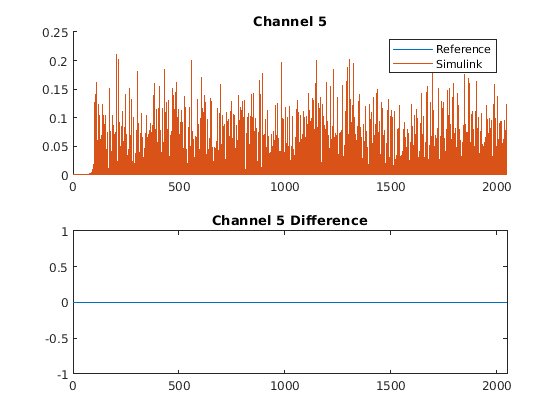

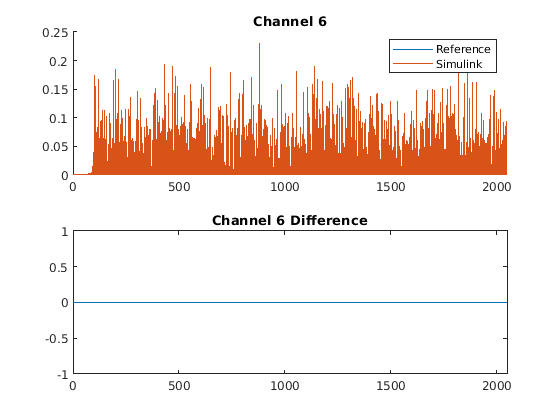

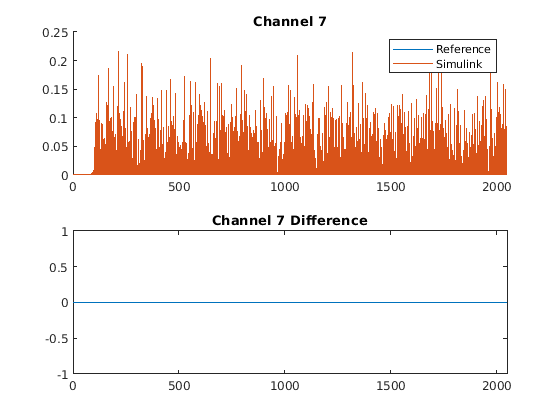

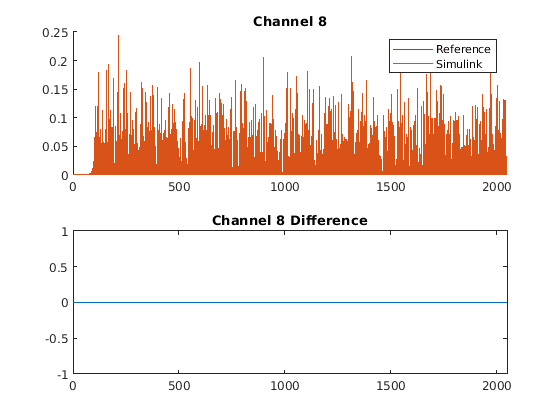

for ii = 1:8
    figure; 
    
    subplot(2,1,1);
    hold on;
    plot(abs(channelizer(ii).o));
    eval(['plot(abs(out.sig' num2str(ii-1) '_o(1:2048))'')']);
    xlim([0 2048]);
    title(['Channel ' num2str(ii)]);
    legend('Reference', 'Simulink');
    
    subplot(2,1,2);
    eval(['plot(abs(channelizer(' num2str(ii) ').o)-abs(out.sig' num2str(ii-1) '_o(1:2048))'')']);
    xlim([0 2048]);
    title(['Channel ' num2str(ii) ' Difference']);
end